# Field Synthesis Proof Illustration Live Script

Supplementary Material to:

**Universal Light-Sheet Generation with Field Synthesis**

Bo-Jui Chang, Mark Kittisopikul, Kevin M. Dean, Phillipe Roudot, Erik Welf and Reto Fiolka.

## Field Synthesis Theorem for a Non-Ideal Line Scan

We want to prove that the sum of the intensity of individual line scans produces a light-sheet illumination pattern equivalent to the average intensity created by a scanned light-sheet.

Let F(x,z) describe the electric field produced by illuminating the entire mask in the back pupil plane. $\hat{F}(k_x,k_z)$ represents the mask at the back pupil plane, the Fourier transform of the electric field.

An individual line scan is represented by the function $T_{a\;} \left(x,z\right)$ and has a Fourier transform $\hat{T}_a(k_x,k_z) = \hat{F}(k_x,k_z)\hat{L}(k_x -a)$.

The intensity of the illumination is represented by the square modulus ${\left|\cdot \;\right|}^{2\;}$. The intensity created by illumination the entire annular mask is $\left| F(x,z) \right| ^2$. The intensity of an individual line scan is $\left| T_a(x,z) \right| ^2$.

A sum of the intensity of individual line scans can be expressed as $\sum_a \left| T_a(x,z) \right|^2$.

An scanned light sheet has a z-profile equivalent to the average of F(x,z) over the x-dimension: $\frac{1}{N} \left|F(x,z) \right|^2 ** |L(x)\delta(z)|^2$ .

Thus we want to prove that $\sum_a \left|T_a(x,z) \right| = \frac{1}{N} \left|F(x,z) \right|^2 ** |L(x)\delta(z)|^2$

## Setup

N = 512;
center = floor(N/2+1);

% Annulus mask at the back focal plane
F_hat = createAnnulus(N, (82+88)/2, 10);
F_hat = imgaussfilt(double(F_hat),0.5);

% Delta function representing the line scan
% L_hat = zeros(N);
% L_hat(:,center) = 1;

% Position of the line scan for demonstration
a = -57;

% x and z coordinates
x = ceil(-N/2):floor(N/2-1);
z = x;

% Gaussian profile
L_sigma = 5;
L_hat = normpdf(x,0,L_sigma);
L_hat = repmat(L_hat,N,1);


% Zoom levels
% 64x64 zoom level
xlims_highzoom = [-1 1]*64+center;
ylims_highzoom = [-1 1]*64+center;

% 128x128 zoom level
xlims_mediumzoom = [-1 1]*128+center;
ylims_mediumzoom = [-1 1]*128+center;

% Utility function to do shifts from back focal plane to object plane
% Note that the shifts are necessary to have the coefficients where fftw
% will expect them
% 0.1 Shift the frequency space representation so the zeroth frequency is at
%     matrix index (1,1)
% 0.2 Perform a 2-D inverse Fourier Transform
% 0.3 Shift the object space representation so that "center" is located
%     in the center of the image
doInverse2DFourierTransformWithShifts = @(X) fftshift( ifft2( ifftshift(X) ) );

## Definition of $\hat{T}_a$, frequency space presentation of each line scan in the back focal plane

We first start at the back pupil plane where we multiply a ring by a line on a pixel-by-pixel basis.


$$\hat{T_a}(k_x,k_z) = \hat{F}(k_x,k_z)\hat{L}(k_x-a)$$


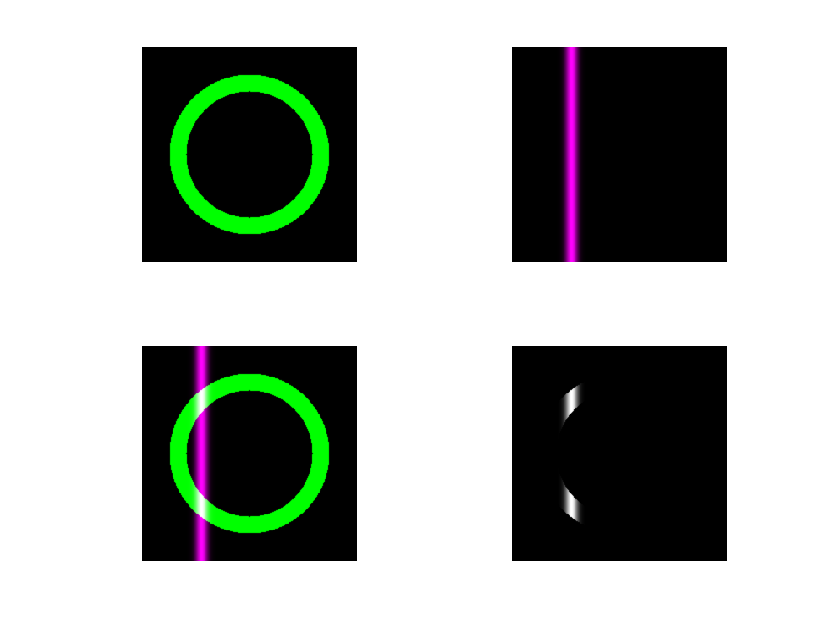

% Calculate T_a_hat

L_hat_shifted = circshift(L_hat,[0 a]);
T_a_hat = F_hat.*L_hat_shifted;

figure;


% Green annulus only
subplot(2,2,1); % Upper left corner
him = imshowpair(F_hat,zeros(512));
xlim(xlims_mediumzoom); ylim(ylims_mediumzoom); 
text(1,1,'F_hat','Color','green');


% Delta magenta only
subplot(2,2,2); % Upper right corner
him = imshowpair(zeros(512),L_hat_shifted);
xlim(xlims_mediumzoom); ylim(ylims_mediumzoom); 

% Green annulus, magenta delta
subplot(2,2,3); % Lower left corner
him = imshowpair(F_hat,L_hat_shifted);
xlim(xlims_mediumzoom); ylim(ylims_mediumzoom);

% White overlap only
subplot(2,2,4); % Lower right corner
him = imshow(T_a_hat,[]);
xlim(xlims_mediumzoom); ylim(ylims_mediumzoom); 

## Equation 10


$$\sum_a |T_a(x,z)|^2 = \sum_a | \mathcal{F}^{-1} \left\{ \hat{T}_a(k_x,k_z) \right\}(x,z) |^2$$


In equation 1, we state the inverse 2-D Fourier transform relationship between the electric field of an instaneous line scan, $T_a(x,z)$. 

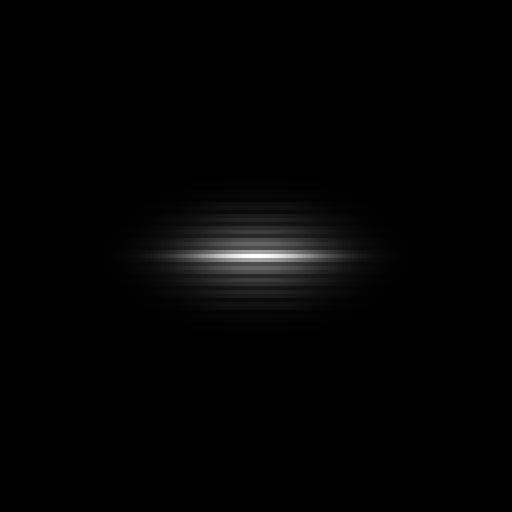

% Save our example "a" for later use
a_selected = a;
T_a_hat_selected = T_a_hat;
L_hat_shifted_selected = L_hat_shifted;

a_sequence = -256:255;
fsGeneratedField = zeros(N);
for a = a_sequence
    L_hat_shifted = circshift(L_hat,[0 a]);
    T_a_hat = F_hat.*L_hat_shifted;
    % 1.1 Shift the frequency space representation so the zeroth frequency is
    %     at matrix index (1,1)
    % 1.2 Perform a 2-D inverse Fourier Transform
    T_a = ifft2(ifftshift(T_a_hat));
    fsGeneratedField = fsGeneratedField + abs(T_a).^2;
end

% 1.3 Shift the object space representation so that "center" is located
%     in the center of the image
fsGeneratedField = fftshift(fsGeneratedField);

figure;
imshow(fsGeneratedField,[]);
xlim(xlims_highzoom); ylim(xlims_highzoom); 

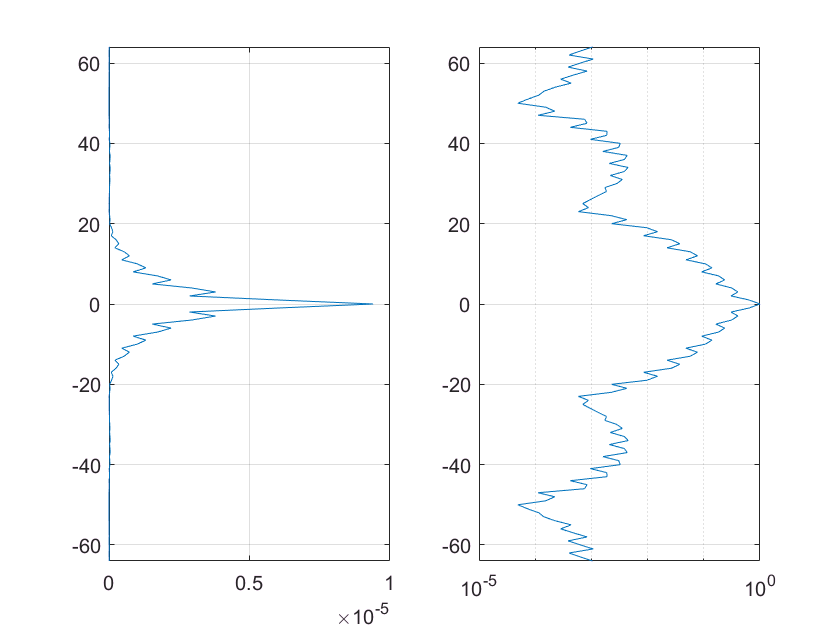

fsGeneratedFieldSlice = fsGeneratedField(:,center);

figure;
subplot(1,2,1);
plot(fsGeneratedFieldSlice,z);
grid on;
ylim(xlims_highzoom-center);

subplot(1,2,2);
semilogx(mat2gray(fsGeneratedFieldSlice)+1e-5,z);
grid on;
ylim(xlims_highzoom-center);



% Restore our example "a"
a = a_selected;
T_a_hat = T_a_hat_selected;
L_hat_shifted = L_hat_shifted_selected;


## Equation 11

In equation 2, we substitute in  the frequency space representation at the back focal plane which we just defined above.


$$\sum_a |T_a(x,z)|^2 = \sum_a | \mathcal{F}^{-1} \left\{ \hat{F}(k_x,k_z)\hat{L}(k_x-a) \right\}(x,z) |^2$$


Note that because $\hat{T}_a$ is not conjugate symmetric, $\hat{T}_a(k_x,k_z) \neq \hat{T}_a^*(-k_x,-k_z)$, the range of$T_a$ is complex valued.

To illustrate this we will focus on a single instaneous line scan at "a". Change the variable "a" above to view another slice.

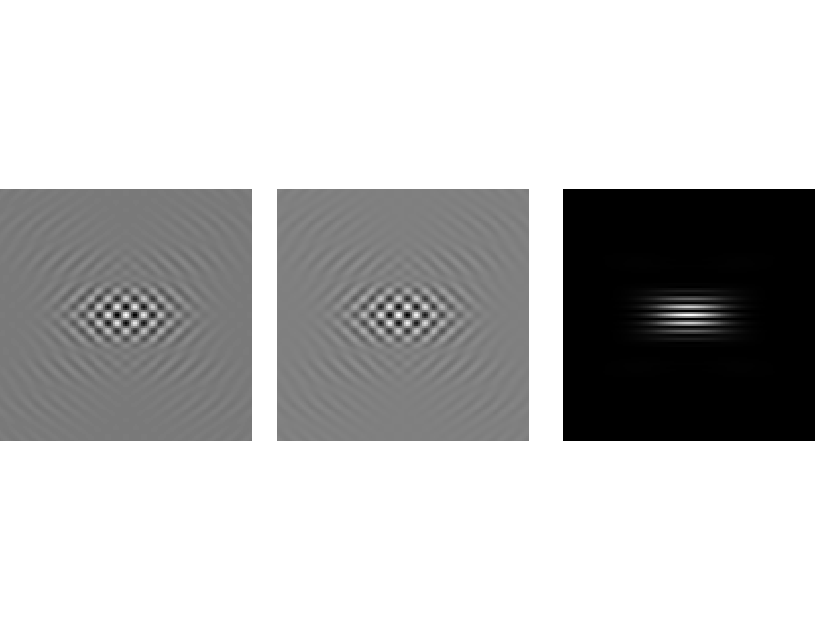

% 2.1 Shift the frequency space representation so the zeroth frequency
%     is at matrix index (1,1)
% 2.2 Perform a 2-D inverse Fourier Transform
T_a = ifft2(ifftshift(T_a_hat));
% 2.3 Shift the object space representation so that "center" is located
%     in the center of the image
T_a = fftshift(T_a);
% Subsequent inverse Fourier Transforms will use
% doInverse2DFourierTransformWithShifts as defined in setup
%  T_a = doInverse2DFourierTransformWithShifts(T_a_hat);

figure;
subplot(1,3,1);
him = imshow(real(T_a),[]);
him.Parent.Position = [0 0 0.3 1];
text(50,50,'Real\{ T_a \}','Color','green');
xlim(xlims_highzoom); ylim(xlims_highzoom); 

subplot(1,3,2);
him = imshow(imag(T_a),[]);
him.Parent.Position = [ 0.33 0 0.3 1];
text(50,50,'Imaginary\{ T_a \}','Color','green');
xlim(xlims_highzoom); ylim(xlims_highzoom); 

subplot(1,3,3);
him = imshow(abs(T_a).^2,[]);
him.Parent.Position = [0.67 0 0.3 1];
text(50,50,'Square Magnitude\{ T_a \}','Color','green');
xlim(xlims_highzoom); ylim(xlims_highzoom); 

## Equation 12


$$\sum_a |T_a(x,z)|^2 = \sum_a | \mathcal{F}^{-1} \left\{ \hat{F}(k_x,k_z) \right\} ** \mathcal{F}^{-1} \left\{\hat{L}(k_x-a) \right\}(x,z) |^2$$


Next we apply the the 2-D Convolution Theorem to observe that $T_a$ is the 2-D convolution of the inverse Fourier Transform of each term.

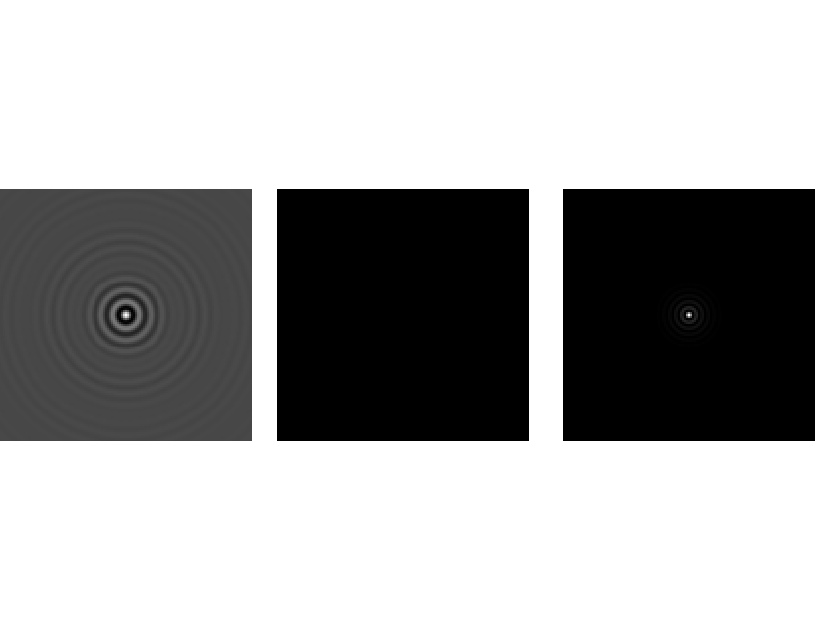

F = doInverse2DFourierTransformWithShifts(F_hat);

figure;
subplot(1,3,1);
him = imshow(real(F),[]);
him.Parent.Position = [0 0 0.3 1];
text(50,50,'Real\{ F \}','Color','green');
% colormap(gca,hot);
xlim(xlims_highzoom); ylim(xlims_highzoom); 


subplot(1,3,2);
him = imshow(imag(F),[0 1]);
him.Parent.Position = [ 0.33 0 0.3 1];
% colormap(gca,hot);
text(50,50,'Imaginary\{ F \}','Color','green');
xlim(xlims_highzoom); ylim(xlims_highzoom); 


subplot(1,3,3);
him = imshow(abs(F).^2,[]);
him.Parent.Position = [0.67 0 0.3 1];
text(50,50,'| F |^2','Color','green');
% colormap(gca,hot);
xlim(xlims_highzoom); ylim(xlims_highzoom); 

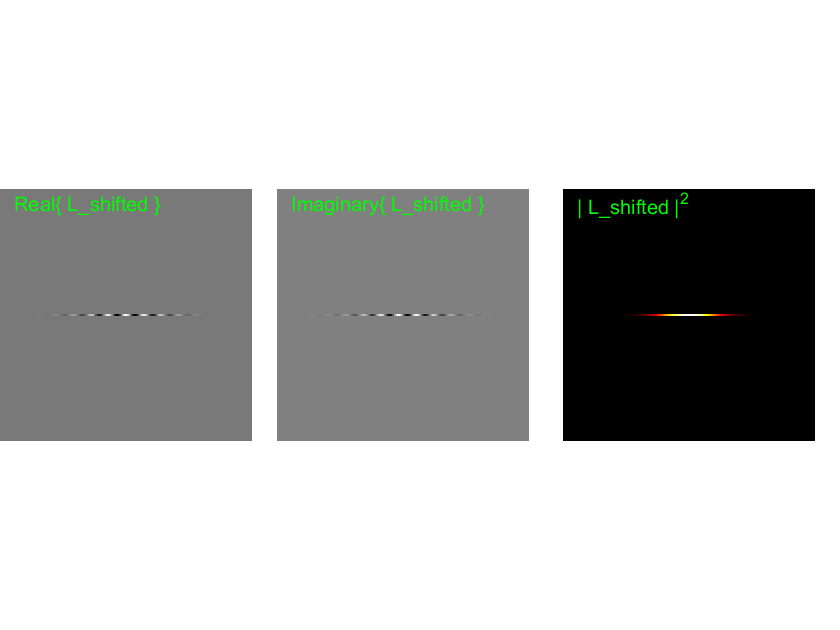

L_shifted_times_delta_z = doInverse2DFourierTransformWithShifts(L_hat_shifted);

figure;
subplot(1,3,1);
him = imshow(real(L_shifted_times_delta_z),[]);
him.Parent.Position = [0 0 0.3 1];
text(256-56,256-56,'Real\{ L\_shifted \}','Color','green','interpreter','tex');
% colormap(gca,hot);
xlim(xlims_highzoom); ylim(xlims_highzoom); 


subplot(1,3,2);
him = imshow(imag(L_shifted_times_delta_z),[]);
him.Parent.Position = [ 0.33 0 0.3 1];
% colormap(gca,hot);
text(256-56,256-56,'Imaginary\{ L\_shifted \}','Color','green');
xlim(xlims_highzoom); ylim(xlims_highzoom); 


subplot(1,3,3);
him = imshow(abs(L_shifted_times_delta_z).^2,[]);
him.Parent.Position = [0.67 0 0.3 1];
text(256-56,256-56,'| L\_shifted |^2','Color','green');
colormap(gca,hot);
xlim(xlims_highzoom); ylim(xlims_highzoom); 

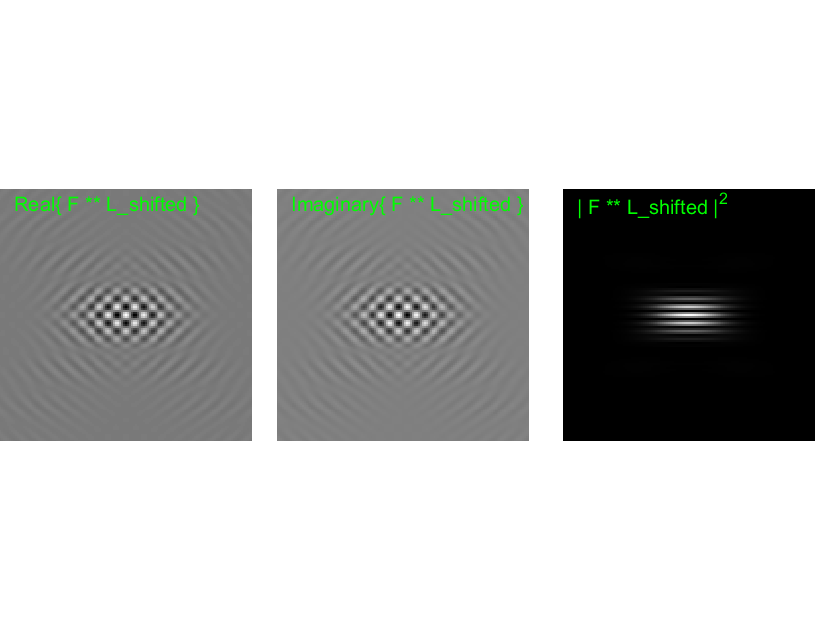

T_a_by_conv = conv2(F,L_shifted_times_delta_z,'same');

figure;
subplot(1,3,1);
him = imshow(real(T_a_by_conv),[]);
him.Parent.Position = [0 0 0.3 1];
text(256-56,256-56,'Real\{ F ** L\_shifted \}','Color','green','interpreter','tex');
% colormap(gca,hot);
xlim(xlims_highzoom); ylim(xlims_highzoom); 


subplot(1,3,2);
him = imshow(imag(T_a_by_conv),[]);
him.Parent.Position = [ 0.33 0 0.3 1];
% colormap(gca,hot);
text(256-56,256-56,'Imaginary\{ F ** L\_shifted \}','Color','green');
xlim(xlims_highzoom); ylim(xlims_highzoom); 


subplot(1,3,3);
him = imshow(abs(T_a_by_conv).^2,[]);
him.Parent.Position = [0.67 0 0.3 1];
text(256-56,256-56,'| F ** L\_shifted |^2','Color','green');
% colormap(gca,hot);
xlim(xlims_highzoom); ylim(xlims_highzoom); 

## Equation 13


$$\sum_a |T_a(x,z)|^2 = \sum_a \left|F(x,z) ** \frac{1}{N}\delta(z)L(x)\exp\left(\frac{2\pi i x a}{N} \right) \right|^2$$


The inverse 2-D Fourier Transform of $\hat{L}(k_x-a)$is $\frac{1}{N}\delta(z)L(x)\exp \left( \frac{2\pi i x a }{N} \right) $. Below we illustrate that the product of the complex exponential and $\delta(z)$ is the same as $\mathcal{F}^{-1}\{ \delta(k_x-a) \}$.

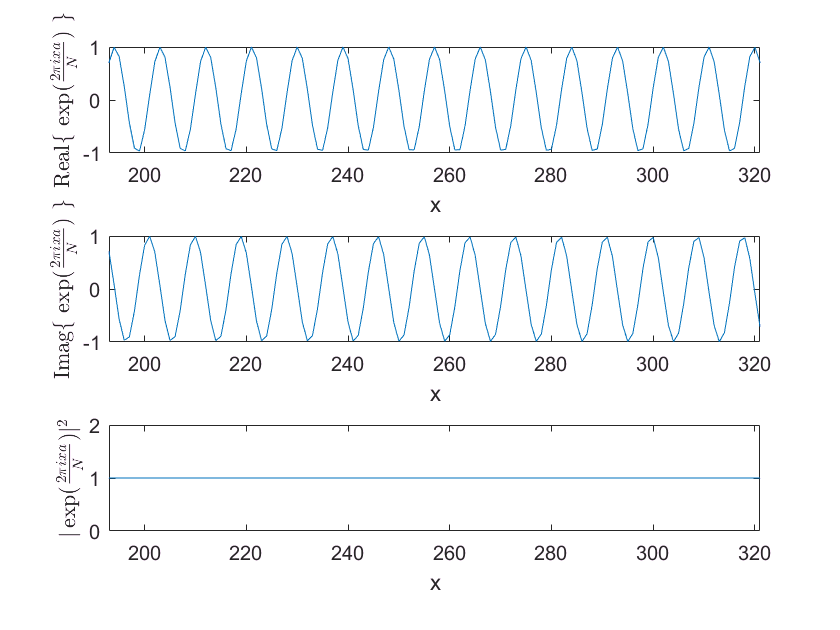

% delta_z = zeros(512);
% delta_z(center,:) = 1/N;
L_times_delta_z = doInverse2DFourierTransformWithShifts(L_hat);

complex_exp = exp(2*pi*1i*x*a/N);

figure;
subplot(3,1,1)
plot(real(complex_exp));
xlim(xlims_highzoom);
xlabel('x');
ylabel('Real\{ $ \exp(\frac{2 \pi i x a }{ N}) $ \}','interpreter','latex');

subplot(3,1,2);
plot(imag(complex_exp));
xlim(xlims_highzoom);
xlabel('x');
ylabel('Imag\{ $ \exp(\frac{2 \pi i x a }{ N}) $ \}','interpreter','latex');


subplot(3,1,3);
plot(abs(complex_exp).^2);
xlim(xlims_highzoom);
ylim([0 2]);
xlabel('x');
ylabel(' $ | \exp(\frac{2 \pi i x a }{ N}) |^2 $','interpreter','latex');

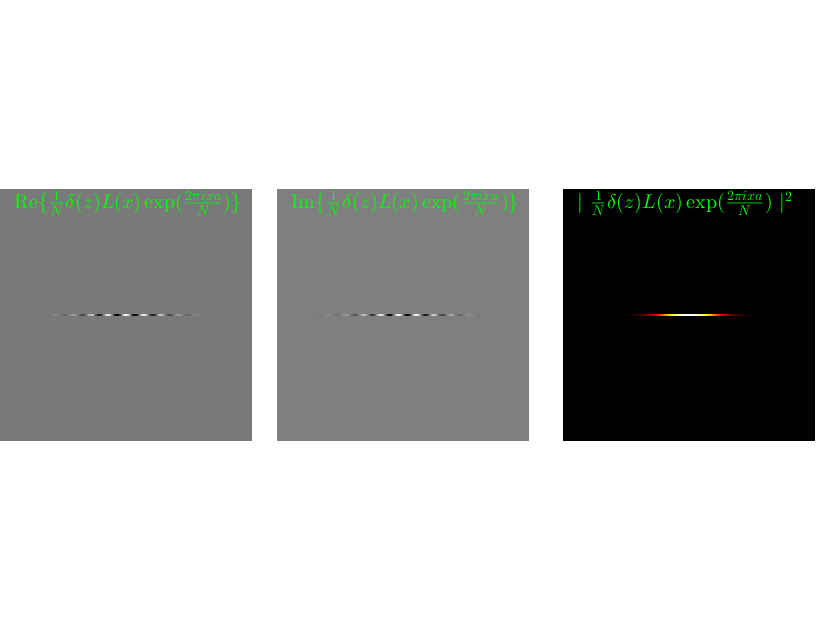




complex_exp = repmat(complex_exp,512,1);
L_shifted_by_product = L_times_delta_z.*complex_exp;

label = '$ \frac{1}{N}\delta(z)L(x)\exp(\frac{2 \pi i x a }{ N}) $';

figure;
subplot(1,3,1);
him = imshow(real(L_shifted_by_product),[]);
him.Parent.Position = [0 0 0.3 1];
text(256-56,256-56,['Re\{' label '\}'],'Color','green','interpreter','latex');
% colormap(gca,hot);
xlim(xlims_highzoom); ylim(xlims_highzoom); 


subplot(1,3,2);
him = imshow(imag(L_shifted_by_product),[]);
him.Parent.Position = [ 0.33 0 0.3 1];
% colormap(gca,hot);
text(256-56,256-56,['Im\{' label '\}'],'Color','green','interpreter','latex');
xlim(xlims_highzoom); ylim(xlims_highzoom); 


subplot(1,3,3);
him = imshow(abs(L_shifted_by_product).^2,[]);
him.Parent.Position = [0.67 0 0.3 1];
text(256-56,256-56,['$ | $ ' label ' $ |^2 $'],'Color','green','interpreter','latex');
colormap(gca,hot);
xlim(xlims_highzoom); ylim(xlims_highzoom); 

## Equation 14


$$\sum_a | T_a(x,z)|^2 = \sum_a \left|\sum_{x'}\sum_{z'} \frac{1}{N} \left[ F(x',z') \exp \left( \frac{2 \pi i (x-x') a}{N} \right) L(x-x')\delta(z-z') \right] \right|^2$$


Next, we can use the definition of 2-D convolution to expand out the expression as two nested summations.

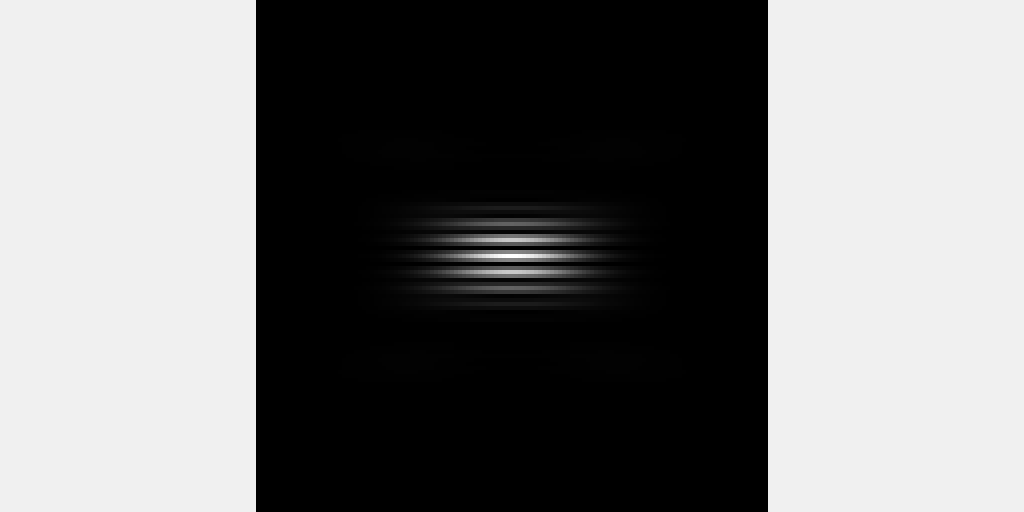

hfig = figure('visible','on');
him = imshow(zeros(N,N*2),[0 1]);
cumulativeSum = zeros(N);
% Technically, we are animated the commuted convolution here, which is equivalent
% Only iterate over 3 rows of z for brevity
for zp=((-1:1)*32)
    for xp=x
        F_shifted = circshift(F,[zp xp]).* complex_exp(center,xp+center);
        cumulativeSum = cumulativeSum + F_shifted.*L_times_delta_z(zp+center,xp+center);
        him.CData = [mat2gray(abs(F_shifted).^2) mat2gray(abs(cumulativeSum).^2)];
        drawnow;
    end
end
xlim(xlims_highzoom+N); ylim(xlims_highzoom); 

The above is an animation. Run this section to see it. In a static document like a PDF, only the last frame will be shown. The cumulative sum also retains its complex character as is shown in the illustration of its real component.

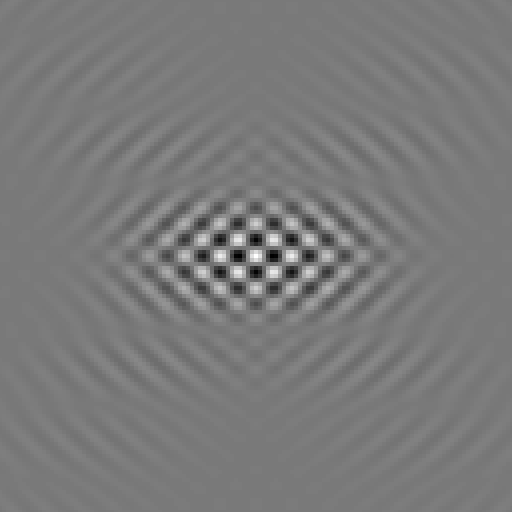

figure; imshow(real(cumulativeSum),[]);
xlim(xlims_highzoom); ylim(xlims_highzoom);

## Equation 15


$$\sum_a | T_a(x,z)|^2 = \frac{1}{N^2} \sum_a \left| \exp \left( \frac{2 \pi i x a}{N} \right)  \sum_{x'}  \left[ F(x',z')L(x-x') \exp \left( -\frac{2 \pi i x' a}{N} \right)  \right] \right|^2$$


Because of the 1-D delta function $\delta(z-z')$in the summation, we only need to perform the summation over x, the middle row. Only the term when $z' = z$ survives.

hfig = figure('visible','on');
him = imshow(zeros(N,N*2),[0 1]);
cumulativeSum = zeros(N);
% Technically, we are animated the commuted convolution here, which is equivalent
% We only iterate over on row
zp = 0;
for xp=x
    F_shifted = circshift(F.*conj(complex_exp),[0 xp]); %exp(2*pi*1i*xp*a/N);
    cumulativeSum = cumulativeSum + F_shifted.*L_times_delta_z(zp+center,xp+center);
    him.CData = [mat2gray(abs(F_shifted).^2) mat2gray(abs(complex_exp.*cumulativeSum).^2)];
    drawnow;
end
xlim(xlims_highzoom+N); ylim(xlims_highzoom); 

Note that the variable cumulativeSum now differs from $T_a$. Let's call that field $Q_a$and observe it is real valued.


$$Q_a(x,z)= \sum_{x'}  \left[ F(x',z')L(x-x') \exp \left( -\frac{2 \pi i x' a}{N} \right) \right]$$



$$T_a(x,z) = \exp \left( \frac{2 \pi i x a}{N} \right) Q_a(x,z)$$


Q_a = cumulativeSum;

figure; imshow(real(complex_exp.*Q_a),[]);
xlim(xlims_highzoom); ylim(xlims_highzoom);

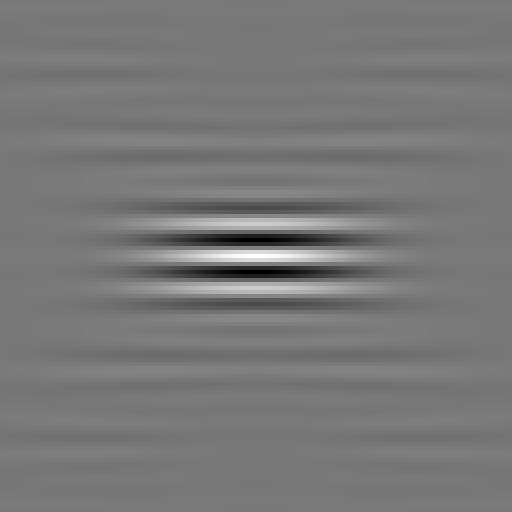

figure; imshow(real(Q_a),[]);
xlim(xlims_highzoom); ylim(xlims_highzoom);

% Note that Q_a is real valued!
figure; imshow(imag(Q_a),[0 1]);
xlim(xlims_highzoom); ylim(xlims_highzoom);

## Equation 16


$$\sum_a | T_a(x,z)|^2 = \frac{1}{N^2} \sum_a \left| \exp \left( \frac{2 \pi i (x) a}{N} \right) \right|^2 \left| \sum_{x'}  \left[ F(x',z')L(x-x') \exp \left( -\frac{2 \pi i x' a}{N} \right)  \right] \right|^2$$


The multiplicative property of the complex modulus allows us to factor out the square modulus of the first complex exponential. The square modulus of that complex exponential is unity, 1, everywhere.

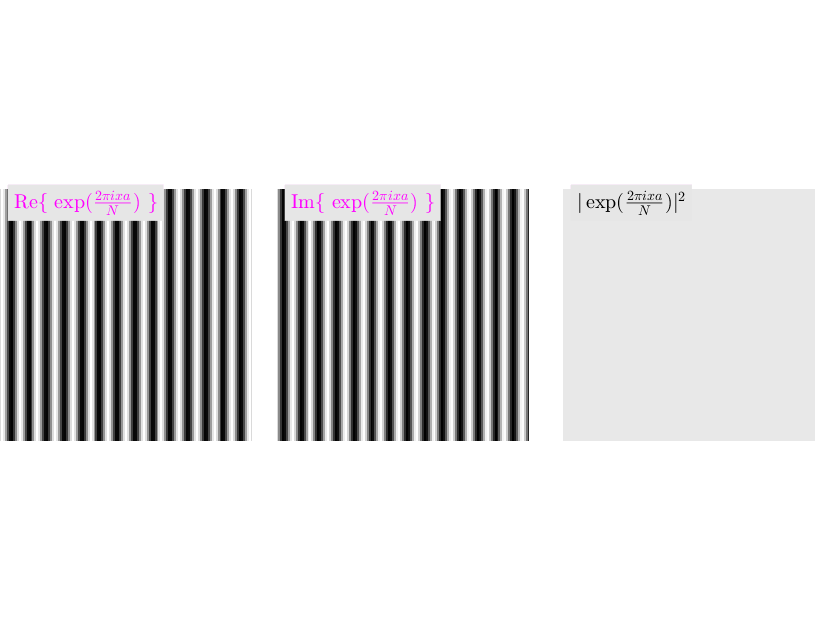

label = '\exp(\frac{2 \pi i x a }{ N})';

figure;
subplot(1,3,1);
him = imshow(real(complex_exp),[]);
him.Parent.Position = [0 0 0.3 1];
text(256-56,256-56,['Re\{ $' label '$ \}'], ...
    'BackgroundColor',[0.9 0.9 0.9],'Color','magenta','interpreter','latex');
% colormap(gca,hot);
xlim(xlims_highzoom); ylim(xlims_highzoom); 


subplot(1,3,2);
him = imshow(imag(complex_exp),[]);
him.Parent.Position = [ 0.33 0 0.3 1];
% colormap(gca,hot);
text(256-56,256-56,['Im\{ $' label '$ \}'], ...
    'BackgroundColor',[0.9 0.9 0.9],'Color','magenta','interpreter','latex');
xlim(xlims_highzoom); ylim(xlims_highzoom); 


subplot(1,3,3);
% Adjust upper color limit so you can see the white square
him = imshow(abs(complex_exp).^2,[0 1.1]);
him.Parent.Position = [0.67 0 0.3 1];
text(256-56,256-56,['$ | ' label ' |^2 $'], ...
    'BackgroundColor',[0.9 0.9 0.9],'Color','black','interpreter','latex');
% colormap(gca,hot);
% colorbar;
xlim(xlims_highzoom); ylim(xlims_highzoom); 

## Equation 17


$$\sum_a | T_a(x,z)|^2 = \frac{1}{N^2} \sum_a  \left| \mathcal{F}_{x'} \left\{  F(x',z)L(x-x') \right\}(a,z) \right|^2$$


We can simplify the expression further using the definition of the 1-D Fourier Transform with respect to $x'$. Note that this creates a field where the x-dimension is frequency space and the z-dimension is in object space. In this non-ideal case, there is now some variation in the x-dimension as seen in the $x-x'$term of $L(x-x')$. For illustrative purposes, we will focus on the $x = 0$ central slice in object space.

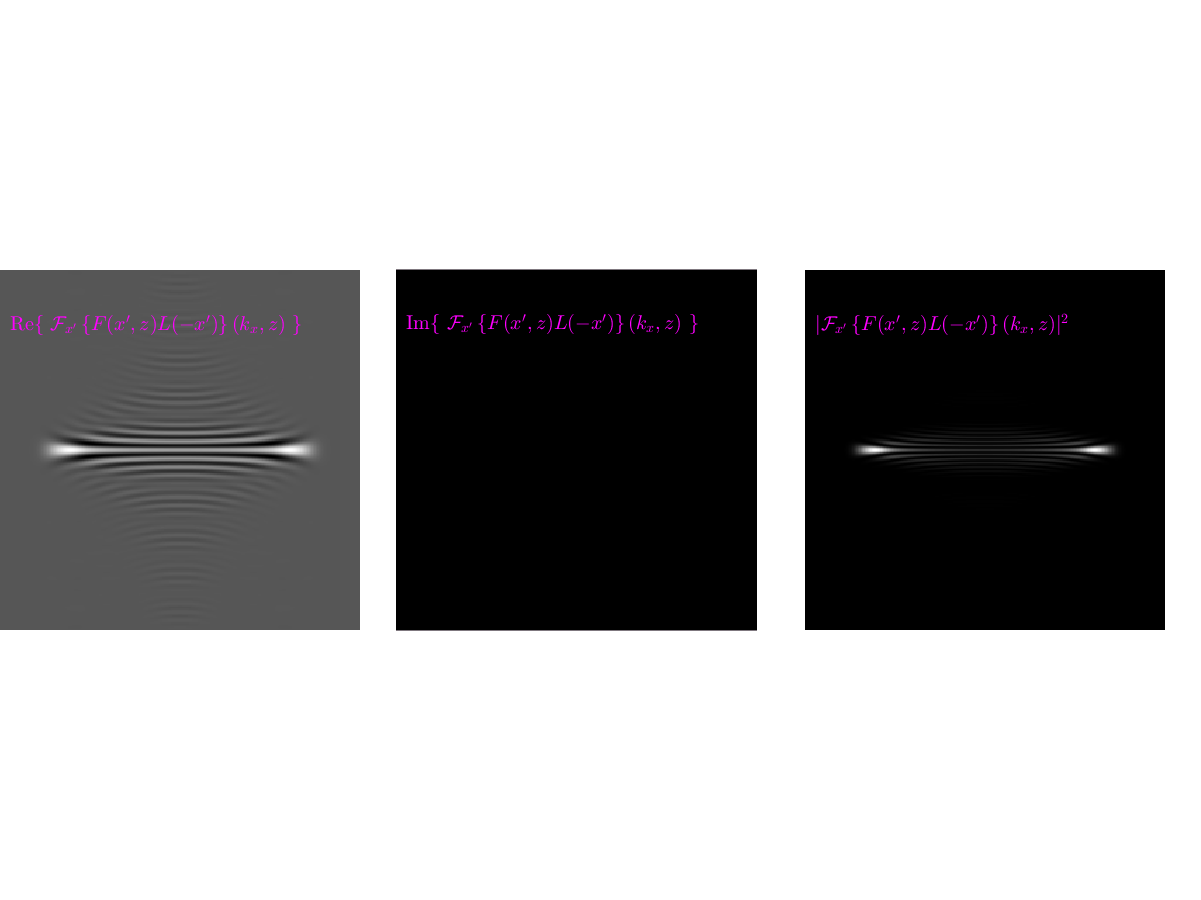

L_flipped = fliplr(L_times_delta_z);
if(mod(size(L_times_delta_z,2),2) == 2)
    % If the dimension is even sized, we need to keep the center in the
    % center by shifting the array over by one
    L_flipped = circshift(L_flipped,[0 1]);
end
% L is only a function of x, and we do not need the \delta(z) now
L_flipped = repmat(L_flipped(center,:),N,1);

one_d_ft = fftshift(fft(ifftshift(F.*L_flipped,2),[],2),2);
label = '\mathcal{F}_{x''} \left\{ F(x'',z)L(-x'') \right\}(k_x,z)';

figure('Position',[0 0 800 600]);
subplot(1,3,1);
him = imshow(real(one_d_ft),[]);
him.Parent.Position = [0 0 0.3 1];
text(256-56-64,256-56-32,['Re\{ $ ' label ' $ \}'],'Color','magenta','interpreter','latex');
% colormap(gca,hot);
xlim(xlims_mediumzoom); ylim(xlims_mediumzoom); 


subplot(1,3,2);
him = imshow(imag(one_d_ft),[0 1]);
him.Parent.Position = [ 0.33 0 0.3 1];
% colormap(gca,hot);
text(256-56-64,256-56-32,['Im\{ $ ' label ' $ \}'],'Color','magenta','interpreter','latex');
xlim(xlims_mediumzoom); ylim(xlims_mediumzoom); 


subplot(1,3,3);
% Adjust upper color limit so you can see the white square
him = imshow(abs(one_d_ft).^2,[]);
him.Parent.Position = [0.67 0 0.3 1];
text(256-56-64,256-56-32,['$ | ' label ' |^2 $'],'Color','magenta','interpreter','latex');
% colormap(gca,hot);
% colorbar;
xlim(xlims_mediumzoom); ylim(xlims_mediumzoom); 

The z-profile of $|T_a(0,z)|^2$ is a one-dimensional Fourier Transform of $F(x,z)L(-x), |\mathcal{F}_{x'} \{F(x',z)L(-x') \}(a,z)|^2$

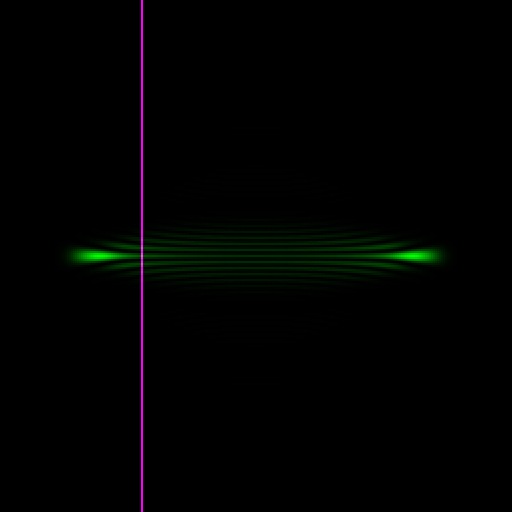

delta_shifted = zeros(size(L_hat));
delta_shifted(:,center+a) = 1;
figure; imshowpair(abs(one_d_ft).^2,delta_shifted);
xlim(xlims_mediumzoom); ylim(xlims_mediumzoom); 

To see this, let the 1-D function $g_a(z) = \mathcal{F}_{x'} \{F(x',z)L(-x') \}(a,z)$

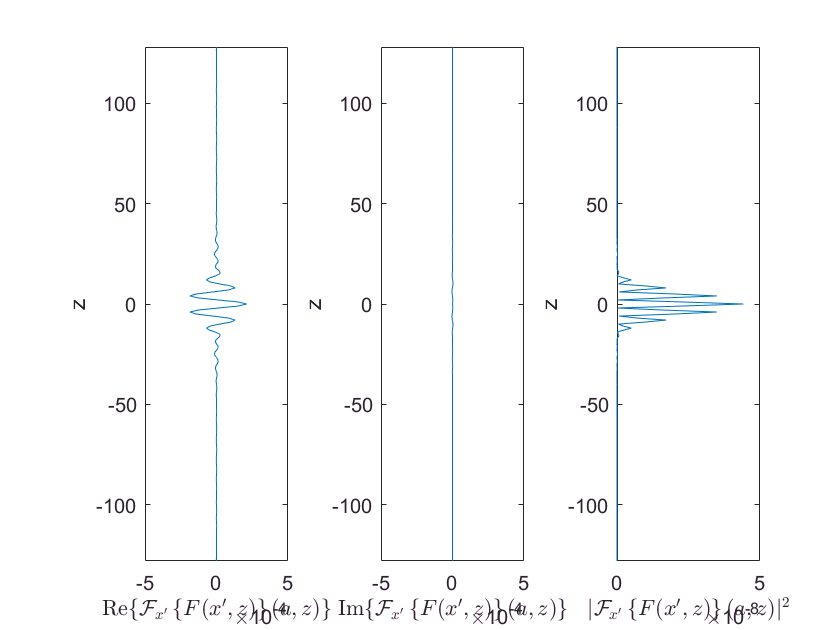

z = x;
g_a = one_d_ft(:,a+center);
label = '\mathcal{F}_{x''} \left\{ F(x'',z) \right\}(a,z)';
figure;
subplot(1,3,1);
plot(real(g_a),z);
xl = xlim;
ylim(xlims_mediumzoom-center);
ylabel('z');
xlabel(['Re\{$ ' label ' $\}'],'interpreter','latex');

subplot(1,3,2);
plot(imag(g_a),z);
xlim(xl);
ylim(xlims_mediumzoom-center);
ylabel('z');
xlabel(['Im\{$ ' label ' $\}'],'interpreter','latex');


subplot(1,3,3);
plot(abs(g_a).^2,z);
ylim(xlims_mediumzoom-center);
ylabel('z');
xlabel(['$ |' label '|^2 $'],'interpreter','latex');

Now that we have followed each instaneous $T_a(x,z) \mbox{ and then } Q_a(x,z)$ through the manipulations, we now consider the summation over "a". 

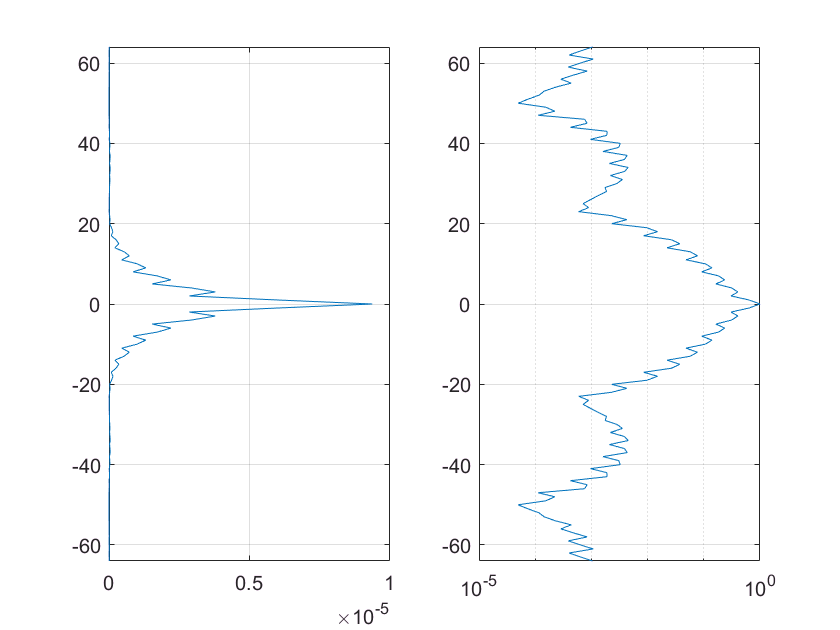

one_d_ft_projection = sum(abs(one_d_ft).^2,2);

figure;
subplot(1,2,1);
plot(one_d_ft_projection,z);
grid on;
ylim(xlims_highzoom-center);

subplot(1,2,2);
semilogx(mat2gray(one_d_ft_projection)+1e-5,z);
grid on;
ylim(xlims_highzoom-center);

## Equation 18

## 
$$\sum_a | T_a(x,z)|^2 = \frac{1}{N} \sum_{x'} | F(x',z)L(x-x')|^2$$


We use Parserval's theorem to equate the sum of the square modulus of the 1-D Fourier transform of the sequence with the sum of the square modulus of the original electric field produced by the mask. The sum of the square modulus of the electric field is a projection in the x' direction. This projection is created by the conventional manner of scanning a beam across a field to create a lightsheet.

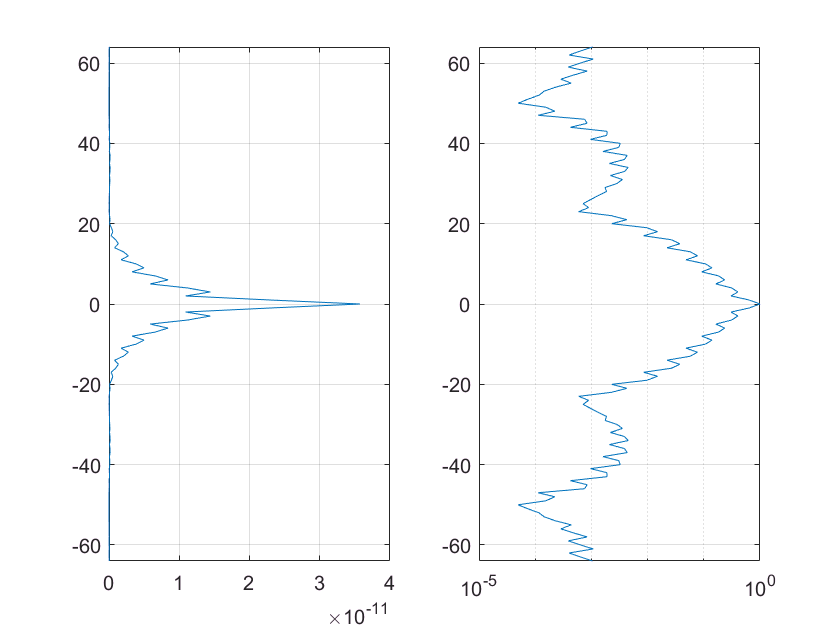

FL_projection = sum(abs(F.*L_flipped).^2,2)/N;

figure;
subplot(1,2,1);
plot(FL_projection,z);
grid on;
ylim(xlims_highzoom-center);

subplot(1,2,2);
semilogx(mat2gray(FL_projection)+1e-5,z);
grid on;
ylim(xlims_highzoom-center);

## Equation 19


$$\sum_a | T_a(x,z)|^2 = \frac{1}{N} \sum_{x'} | F(x',z)|^2 |L(x-x')|^2$$


By the properties the complex square modulus, we can separately take the square modulus of the F and L portions of the summand.

FL_projection_split = sum(abs(F).^2.*abs(L_flipped).^2,2)/N;

figure;
subplot(1,2,1);
plot(FL_projection_split,z);
grid on;
ylim(xlims_highzoom-center);

subplot(1,2,2);
semilogx(mat2gray(FL_projection_split)+1e-5,z);
grid on;
ylim(xlims_highzoom-center);

## Equation 20


$$\sum_a | T_a(x,z)|^2 = \frac{1}{N} \sum_{z'} \sum_{x'} | F(x',z')|^2 |L(x-x')\delta(z-z')|^2$$


Next we reintroduce the delta function in terms of z to restore the double summation. The reason for this is to convert the 1-D convolution in Equation 19 into a 2-D convolution in Equation 21.

## Equation 21


$$\sum_a | T_a(x,z)|^2 = \frac{1}{N} | F(x,z)|^2 ** |L(x)\delta(z)|^2$$


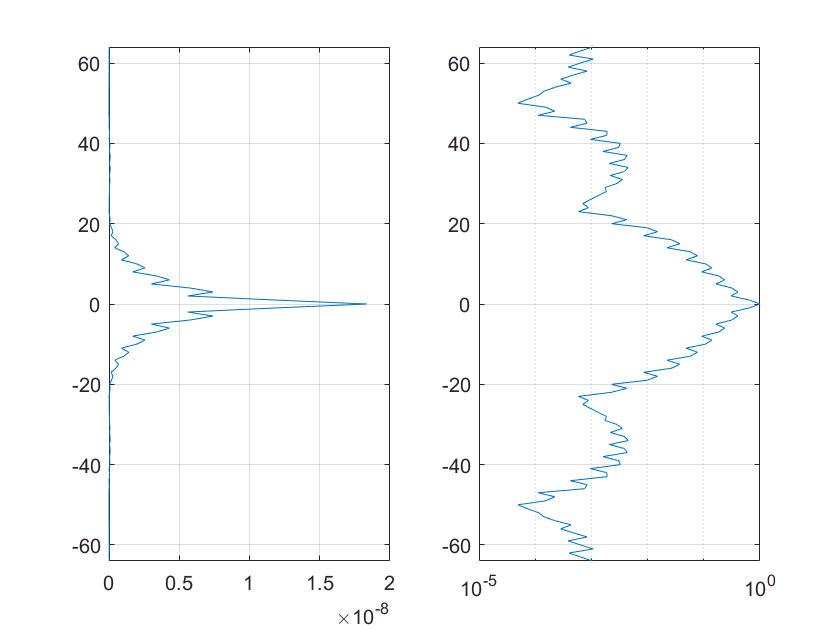

% Linear convolution
linearConv = conv2(abs(F).^2,abs(L_times_delta_z).^2,'same');
figure;
subplot(1,2,1);
plot(linearConv(:,center),z);
grid on;
ylim(xlims_highzoom-center);

subplot(1,2,2);
semilogx(mat2gray(linearConv(:,center))+1e-5,z);
grid on;
ylim(xlims_highzoom-center);

figure;
imshow(linearConv,[]);
xlim(xlims_highzoom); ylim(xlims_highzoom); 

% Circular convolution
% This will work more generally where L(x) does not go to zero near the
% boundaries
cconv2 = @(x,y,~) fftshift(ifft2(fft2(ifftshift(x)).*fft2(ifftshift(y))));
circConv = cconv2(abs(F).^2,abs(L_times_delta_z).^2,'same');

Error using FieldSynthesisProofIllustrationNonIdeal>@(x,y)fftshift(ifft2(fft2(ifftshift(x)).*fft2(ifftshift(y))))
Too many input arguments.

figure;
subplot(1,2,1);
plot(circConv(:,center),z);
grid on;
ylim(xlims_highzoom-center);

subplot(1,2,2);
semilogx(mat2gray(circConv(:,center))+1e-5,z);
grid on;
ylim(xlims_highzoom-center);
figure;
imshow(circConv,[]);
xlim(xlims_highzoom); ylim(xlims_highzoom); 
figure;
imshowpair(circConv,fsGeneratedField);
xlim(xlims_highzoom); ylim(xlims_highzoom); 

% Room mean sqare 
sqrt(sum(abs(fsGeneratedField(:)-circConv(:)).^2))

We have thus proved the Field Synthesis theorem for an arbitrary line profile.